# フィット概要

①データの準備

・自己相関関数を用意。tableを作成する

[tau, cor]

dataframe = table((TAU)', (COR)');

### 1拡散成分,no tripletのモデル式　one-component diffusion  (p.202) 

beta0 = [diffusion_time , N]

b(1):diffusion_time [s]   

b(2):N

x(:,1) = tau 

if COMPONENT == 1
    beta0 = [10^-2, 30];
    modelfun = @(b, x) 1+b(2)^(-1) .* (1 + x./ b(1)).^(-1) .* (1 + x./ (b(1).*SP^2)).^(-0.5);
end

### 2成分拡散 no triplet

beta0 = [diffusion_time_fast, F_fast,  diffusion_time_slow , F_slow, N]

b(1):diffusion_time_fast(速い成分の拡散時間) [s]   

b(2):F_fast(速い成分の割合)

b(3):diffusion_time_slow(遅い成分の拡散時間) [s]   

        F_slow(遅い成分の割合) =** 1-b(2)**

b(4):N

x(:,1) = tau 

if COMPONENT == 2
    beta0 = [0.001, 0.5, 1, 20]
    modelfun = @(b, x) 1+b(4)^(-1) .* ( (b(2).*(1 + x./ b(1)).^(-1) .* (1 + x./ (b(1).*SP^2)).^(-0.5) ) + ( (1-b(2)).*(1 + x./ b(3)).^(-1) .* (1 + x./ (b(3).*SP^2)).^(-0.5)) );
end

beta0 =     0.0010    0.5000    1.0000   20.0000


②非線形モデルをデータに当てはめる

[`mdl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6-mdl) `= fitnlm(`[`tbl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6_sep_shared-tbl)`,`[`modelfun`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-modelfun)`,`[`beta0`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-beta0)`)` は、`modelfun` で指定されたモデルをテーブルまたはデータセット配列 `tbl` 内の変数に近似し、非線形モデル `mdl` を返します。

`(`[`mdl`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6-mdl?browser=F1help) `= fitnlm(x(説明変数),`[`y`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#d117e377697)`（目的変数）,`[`modelfun`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-modelfun?browser=F1help)`,`[`beta0`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-beta0?browser=F1help)`)` は、列ベクトル `y` を応答変数として、行列 `X` の列を予測子変数として使用)

mdl = fitnlm(dataframe, modelfun, beta0)

mdl = 非線形回帰モデル: 
    Var2 ~ 1 + b4^( - 1)*((b2*(1 + x/b1)^( - 1)*(1 + x/(b1*SP^2))^( - 0.5)) + ((1 - b2)*(1 + x/b3)^( - 1)*(1 + x/(b3*SP^2))^( - 0.5)))

推定された係数: 
          Estimate       SE        tStat       pValue   
          ________    _________    ______    ___________

    b1    0.015053    0.0033854    4.4464     2.3467e-05
    b2     0.17755     0.020466    8.6755     1.0367e-13
    b3       18.46      0.13116    140.75    5.1044e-113
    b4       10.07      0.25918    38.852     1.5955e-60


観測数: 100、誤差の自由度: 96
平方根平均二乗誤差: 0.000448
決定係数: 0.999、自由度調整済み決定係数 0.999
F 統計量とゼロ モデルの比較: 1.43e+08、p 値 は 4.94e-324 です

③得られた係数

parms = (mdl.Coefficients.Estimate)'

parms =     0.0151    0.1776   18.4602   10.0697


④プロット＆save

Before Fitting vs After Fitting

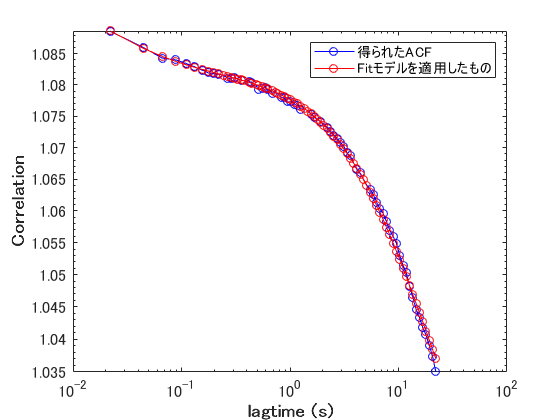

figure
original_vs_fit(TAU, COR, TAU, modelfun(parms,TAU))

%saveas(gcf,sprintf("output/0620/beforeFit_vs_afterfit/0622_%s.png", conc))

After Fitting vs ZEN

% addpath('func') 
% afterFit_vs_ZEN(tau, modelfun_1D1T(parms,tau), tau_zen, cor_zen, parms(4) ,modelfun_1D1T(parms,parms(4)))
% %saveas(gcf,sprintf("output/0620/afterfit_vs_ZEN/0622_%s.png", conc))